**Question 2**

We suppose that there are p students in a class each of whom must be allocated to work in a group on exactly one of *q* problems. Each student i has expressed a preference order for each problem j, taking values 1, 2, . . . , *q*, where 1 denotes the student’s top preference and *q* denotes their least favourite. Assume the preferences are provided in a *p×q* matrix $C_{i,j}$ . The binary decision variables $x_{i,j}$ indicate whether student *i* is matched to problem *j*, and can be unravelled as a vector *x*. We suppose that the objective is to minimise 


$$\frac{1}{p}\sum_{i,j} C_{\textrm{ij}} x_{\textrm{ij}}$$


i.e., the preference order of the problem actually allocated to each student, averaged over the class.

**a) Write down conditions on x that ensure each student is allocated to exactly one problem. Exhibit and explain Matlab code for use with intlinprog that builds the associated constraint matrix.**

To ensure each student is each assigned to one problem, p equality constraints are made of the general form:


$$\sum_{j=1}^q x_{p,j} =1$$


$C_{i,j}$ of the shape *p×q* is unravelled to form the vector *X* of the form:


$$X=\left\lbrack x_{1,1\;} ,{\;x}_{1,2\;} ,\cdots \;,{\;x}_{1,\;q-1} \;,\;x_{1,q} \;,{\;x}_{2,1} \;,\;x_{2,2} \;,\cdots {\;,\;x}_{p,\;q-1} \;,x_{p,q} \right\rbrack$$


The resulting $A_{\textrm{eq}}$ and $b_{\textrm{eq}}$ matrices take on the following form:

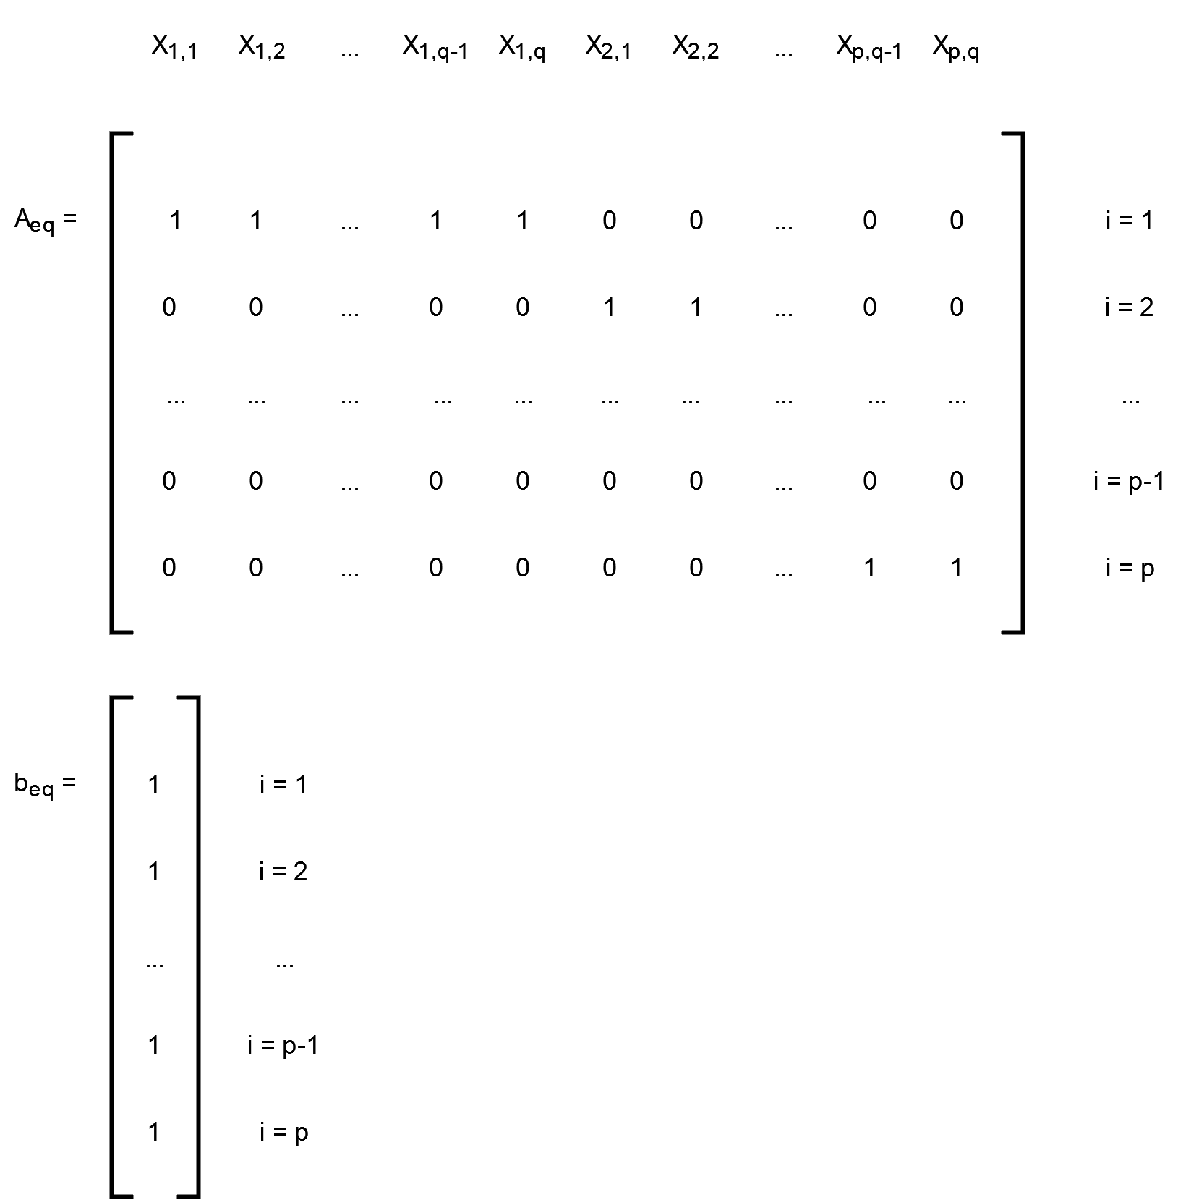

The application of these constraints in code is shown below

% Set up the problem variables
p = 5;
q = 2;

% Initialise Aeq
Aeq = zeros(p, p*q);

% Iteratively populate each new row corresponding to its unravelled postion in X
shift = 1;
for i = 1:p
    Aeq(i, shift:i*q) = 1;
    shift = shift + q;
end
Aeq

Aeq =      1     1     0     0     0     0     0     0     0     0
     0     0     1     1     0     0     0     0     0     0
     0     0     0     0     1     1     0     0     0     0
     0     0     0     0     0     0     1     1     0     0
     0     0     0     0     0     0     0     0     1     1



beq = ones(p, 1);
beq

beq =      1
     1
     1
     1
     1


% The values of each x variable are constrained to one by setting the lb, ub and intcon 
% inputs to intlinprog

% Enforces all results to be integer values
intcon = ones(p, 1);

% Enforces binary results
lb = zeros(p*q,1);
ub = ones(p*q, 1);


**(b) Write down conditions that ensure problem *****j***** has no fewer than **${\mathit{\mathbf{g}}}_{\min }$** and no more than **${\mathit{\mathbf{g}}}_{\max }$** students allocated to it, where **${\mathit{\mathbf{g}}}_{\min }$** and **${\mathit{\mathbf{g}}}_{\max }$** are non-negative integers. Exhibit and explain Matlab code for use with intlinprog that builds the associated constraint matrices.**

To ensure each group is assigned between $g_{\min }$ and $g_{\max }$ students, 2*×q* number of inequality constraints are made of the general forms:


$$\sum_{i=1}^p x_{i,q} \le g_{\max }$$



$$-\sum_{i=1}^p x_{i,q} \le {-g}_{\min }$$


Using the same unravelled form of $C_{\textrm{ij}}$ outlined in part a, the following general inequality matrices *A*, and *B *can be formed:

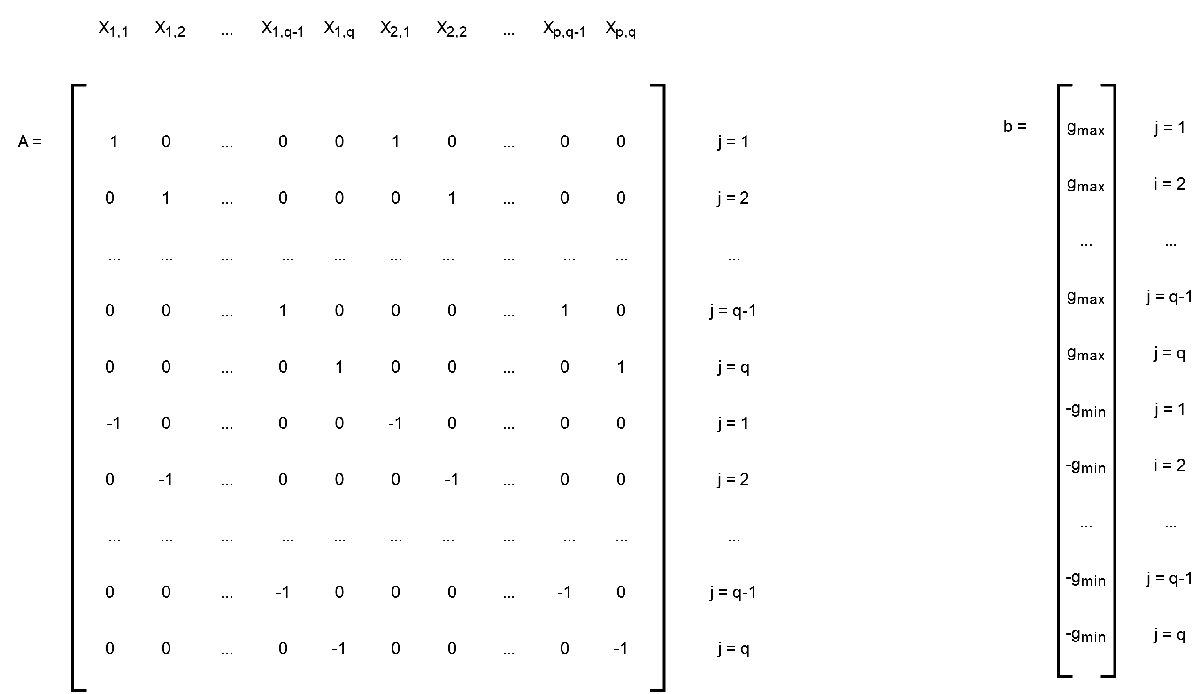

This is demonstrated in the code snippet below:

% Define gmax and gmin
gmax = 5;
gmin = 3;

% Build the inequality matrices A and b
pattern = eye(q);
A_max = repmat(pattern, 1, p);
b_max = gmax * ones(q, 1);

A_min = -A_max;
b_min = -gmin * ones(q, 1);

% Concatanate the min and max inequality matrices
A = [A_max; A_min]

A =      1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1
    -1     0    -1     0    -1     0    -1     0    -1     0
     0    -1     0    -1     0    -1     0    -1     0    -1


b = [b_max; b_min]

b =      5
     5
    -3
    -3


**(C) Complete, exhibit, and explain the intlinprog call to solve the problem, and run it using the data (ProblemRankData - sheet1.csv) supplied with the Lab 02 sheet.**

**Set (e.g.) gmin = 3 and gmax = 5 for all problems**

Mixing all the steps together is shown below

% Load in problem data
C = readmatrix('ProblemRankData.csv');

% Unravel C into one dimensional array
X = reshape(C', [], 1);

% Determine hyperparameters of problem from data
q = width(C);
p = length(C);

% Set min, max group sizes
gmin = 3;
gmax = 5;

% Initialise Aeq
Aeq = zeros(p, p*q);

% Iteratively populate each new row corresponding to its unravelled postion in X
shift = 1;
for i = 1:p
    Aeq(i, shift:i*q) = 1;
    shift = shift + q;
end

beq = ones(p, 1);

% Build the inequality matrices A and b
pattern = eye(q);
A_max = repmat(pattern, 1, p);
b_max = gmax * ones(q, 1);

A_min = -A_max;
b_min = -gmin * ones(q, 1);

% Concatanate the min and max inequality matrices
A = [A_max; A_min];
b = [b_max; b_min];

% Enforce all results to be integer values
intcon = ones(p, 1);

% Enforce binary results
lb = zeros(p*q,1);
ub = ones(p*q, 1);

% Apply intlinprog func
x = intlinprog(X,intcon,A,b,Aeq,beq,lb,ub);

LP:                Optimal objective value is 83.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because
the
objective value is within a gap tolerance of
the optimal value,
options.AbsoluteGapTolerance = 0 (the
default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the
default value).



Within the output, a objective value is given along with the values for X in x

% The unravveling of the cost matrix can now be reversed to determine the groupings
solutions = reshape(x, q, p)';

In the choices output, the columns refer to the groups and the rows refer to the students. From eyeballing it can be seen that the choices are all low numbers and there is only one output per row.

% Dot product with C to see the actual choices made
choices = C .* solutions

choices =      0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     3     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     2
     0     0     0     2     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1


**(d) Write down a constraint which ensures that no student gets allocated worse than (say) their r th reference, where r is a (smallish) positive integer, and exhibit and explain Matlab code which enforces this constraint.**

An additional constraint can be introduced to enforce that no student is allocated worse than a set value. It takes on the same geometric form as the equality matrix outlined in part A. However, the values in the matrix will be multiplied by there corresponding Cost value in C 


$$\sum_{j=1}^q {C\ldotp \;x}_{p,j} \le r$$


r = 4;

% Initialise A3
A3 = zeros(p, p*q);

% Iteratively populate each new row corresponding to its unravelled postion in X
shift = 1;
for i = 1:p
    A3(i, shift:i*14) = C(i, :);
    shift = shift + 14;
end

% Set constraint value
b3 = r * ones(p, 1);

% Concatanate new constraints to original
Ar = [A; A3];
br = [b; b3];

% Reapply intlinprog func
[x, fval, exitFlag] = intlinprog(X,intcon,Ar,br,Aeq,beq,lb,ub);

LP:                Optimal objective value is 83.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because
the
objective value is within a gap tolerance of
the optimal value,
options.AbsoluteGapTolerance = 0 (the
default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the
default value).



**(e) Explore the quality of different assignments, by varying the set-up. Here are some of the things you might (for example) try:    **

`    • `**Vary gmin and gmax, or even allowing them to be different for different problems, thus potentially even removing some problems.**

    **• Set a hard limit r on the worst preference allocated.**

`    • `**Replace cij with (e.g.) **$C_{\textrm{ij}}^2$** or higher powers etc., what does this do?**

`    • `**Does randomising the order of the rows in the cost matrix have any effect?**

By playing around with the group sizes, the optimal objective values can be changed and optimised. For figures 2.1, 2.2 and 2.3, the objective values are 83, 86 and 76 respectively. By increasing the max and decreasing the min in conjuction, the more optimal a solution can be derived.

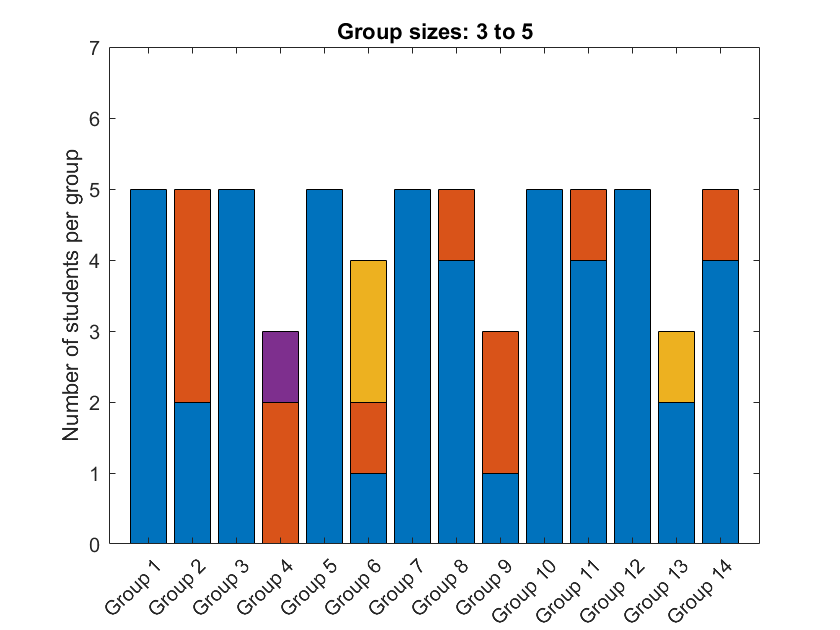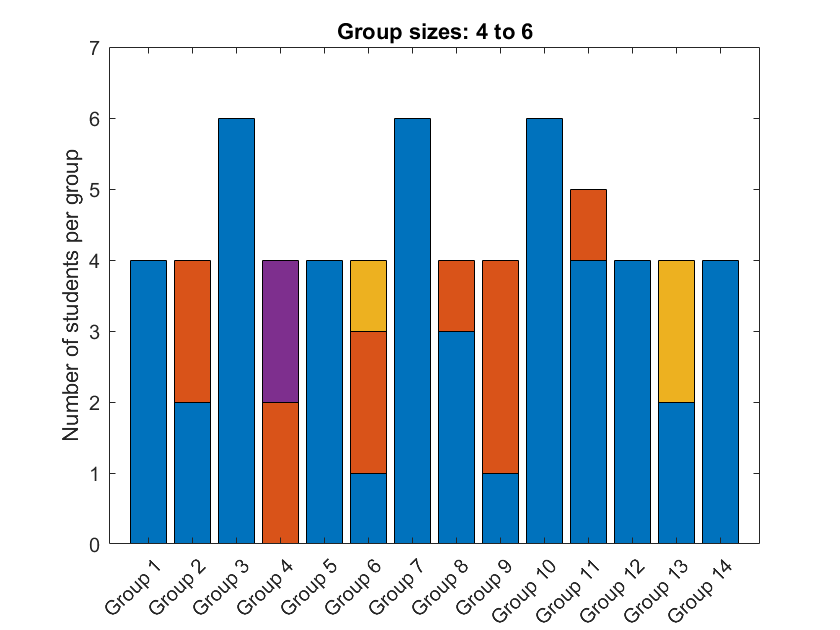

Figure 2.1 Grouping [3-5]                                             Figure 2.2 Grouping [4-6]

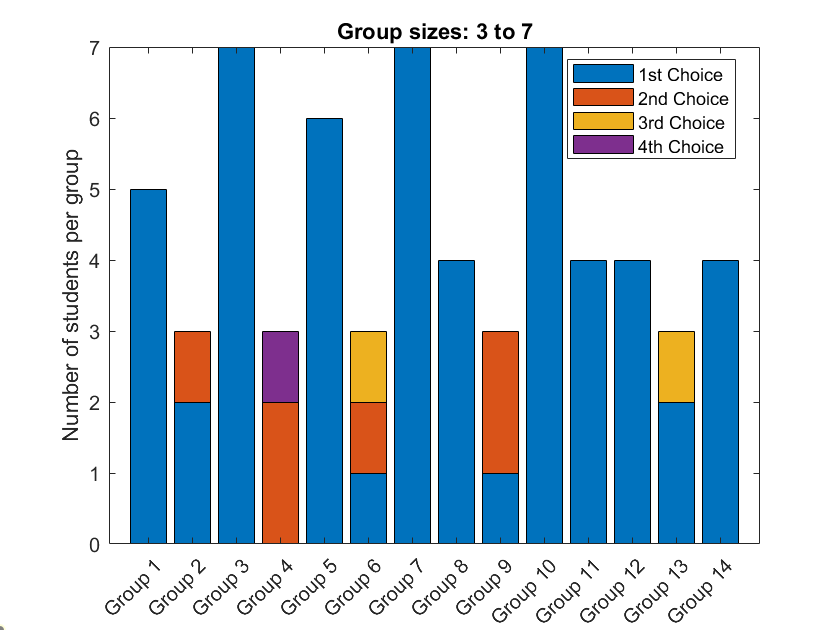

Figure 2.3 Grouping [3-7]

It can be seen from the graphs above that Group 4 and Group 6 are both unpopular groups. By setting their min and max sizes to 0 in the b matrix, they can effectively be removed from the problem. The result of doing this can be seen in figures 2.4 and 2.5 below. The objective values of the figures is 72 and 77 respectively.

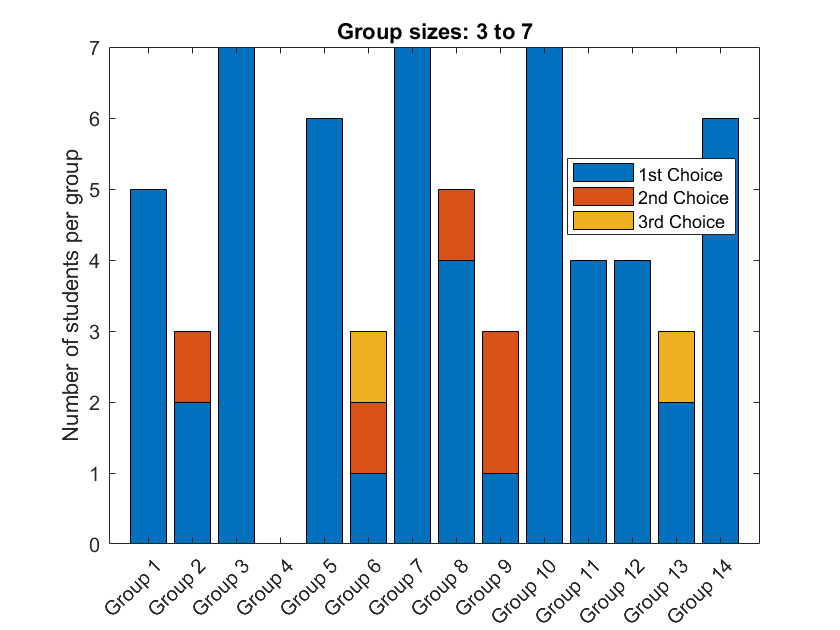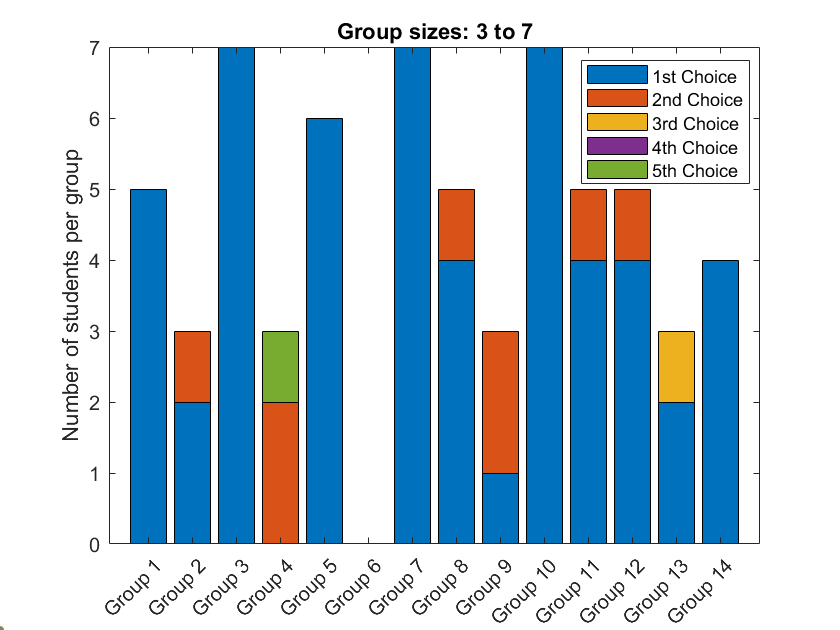

Figure 2.4: Group 4 removed                                     Figure 2.5: Group 6 removed

The objective function can be manipulated to punish worse options non-linearly by raising the entire equation by a power. This is done in the following code snipper:

% Re-caclulate the objective function X
X_sqaured = X.^2;

When applied to the same parameters as shown in figures 2.4 and 2.5, the resulting figures below are derived.

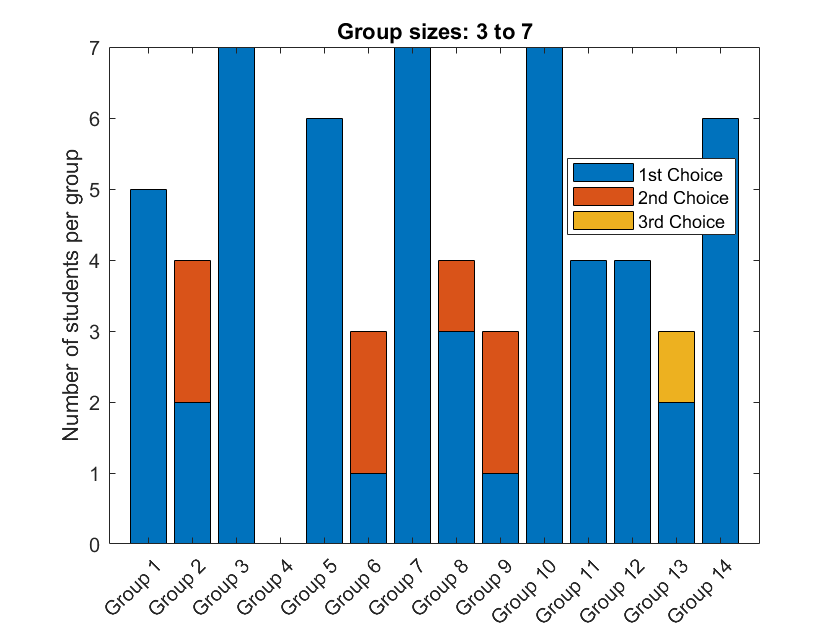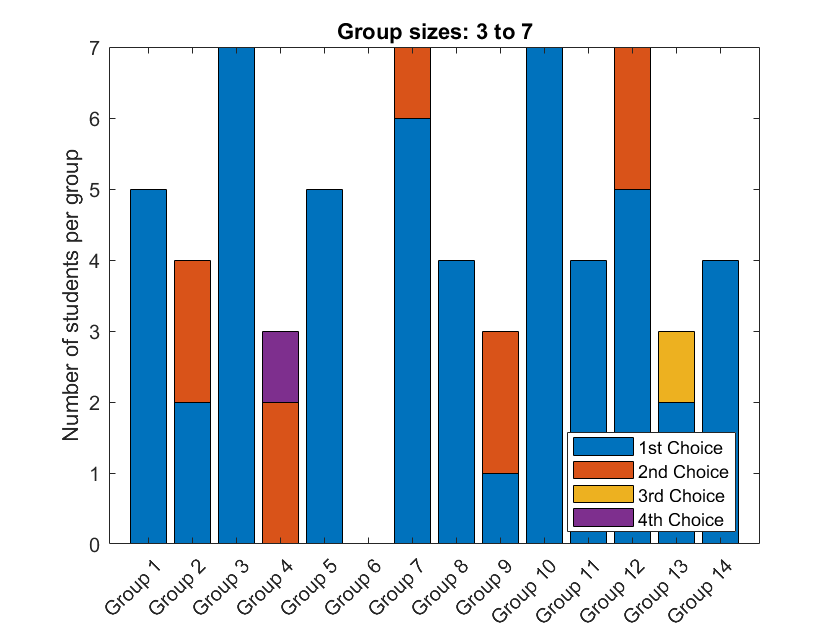

Figure 2.6: Objective function squared                      Figure 2.7: Objective function squared

In both cases, the number of higher order choices have been reduced. The new objective function values have now greatly increased and no longer signify the overall success of the optmisation: effectively a new problem has been defined to satisfy the intial objective.

Continuing on, the next code block experiments with what happens when the order of C is randomised and the resultant groupings are compared.

% Track students initial position in C
studentI = 1:p;

% Create random indexes for the C matrix
ix = randperm(p);

% Randomise C and studentI in the same way
C_rand = C(ix, :);
studentI_rand = studentI(ix);

% Re-apply intlinprog
X_rand = reshape(C_rand', [], 1);
x_rand = intlinprog(X_rand,intcon,A,b,Aeq,beq,lb,ub);

LP:                Optimal objective value is 83.000000.                                            


Optimal solution found.

Intlinprog stopped at the root node because
the
objective value is within a gap tolerance of
the optimal value,
options.AbsoluteGapTolerance = 0 (the
default value). The intcon variables are
integer within tolerance,
options.IntegerTolerance = 1e-05 (the
default value).



The objective value is unchanged. However this does not mean the solutions are not different. The next block unshuffles the solutions and compares the groupings per person. Results can differ in this case where multiple students have selected the same preferences, especially for their top choices.

% Extract solutions from x
solutions_rand = reshape(x_rand, q, p)';

% Solutions need to be unrandomised to compare them against the non randomised solutions
solutions_unshuffled = zeros(size(C));

% Unshuffle solutions
for i = 1:p
    index = find(studentI_rand==i);
    solutions_unshuffled(i, :) = solutions_rand(index, :);
end

% Check for differences
if isequal(solutions, solutions_unshuffled)
    disp('Solutions are the same')
else
    disp('Solutions are different')
end

Solutions are different
